# Dynamic model of a manipulator robot under gravity

#### Using a Lagrangian formulation in symbolic form

clear all
close all
clc

% Manipulator joints structure
manipulator = 'PPR'

manipulator = 'PPR'

motion_axis = 'XYZ'

motion_axis = 'XYZ'

num_joints = strlength(manipulator); manipulator = num2cell(manipulator); 

% define symbolic variables
m = sym('m', [1 num_joints])

$$m = \left(\begin{array}{ccc} m_{1} & m_{2} & m_{3} \end{array}\right)$$

d = sym('d', [1 num_joints])

$$d = \left(\begin{array}{ccc} d_{1} & d_{2} & d_{3} \end{array}\right)$$

l = sym('l', [1 num_joints])

$$l = \left(\begin{array}{ccc} l_{1} & l_{2} & l_{3} \end{array}\right)$$

q = sym('q', [1 num_joints])

$$q = \left(\begin{array}{ccc} q_{1} & q_{2} & q_{3} \end{array}\right)$$

q_dot = sym('q_dot_%d', [1 num_joints])

$$q\_dot = \left(\begin{array}{ccc} {\dot{q}}_{1} & {\dot{q}}_{2} & {\dot{q}}_{3} \end{array}\right)$$

q_ddot = sym('q_ddot_%d', [1 num_joints])

$$q\_ddot = \left(\begin{array}{ccc} {\ddot{q}}_{1} & {\ddot{q}}_{2} & {\ddot{q}}_{3} \end{array}\right)$$

u = sym('u', [1 num_joints])

$$u = \left(\begin{array}{ccc} u_{1} & u_{2} & u_{3} \end{array}\right)$$

%syms(sym('I%dxx', [1 num_joints]))
%syms(sym('I%dyy', [1 num_joints]))
%syms(sym('I%dzz', [1 num_joints]))
% I_c_zz = sym('I_c%d_zz', [1, num_joints])
I = num2cell(NaN(1, num_joints));
for i=1:num_joints
    Ixx = sym(sprintf('I%dxx', i));
    Iyy = sym(sprintf('I%dyy', i));
    Izz = sym(sprintf('I%dzz', i));
    I{i} = diag([Ixx, Iyy, Izz]);
end
F = sym('f', [1 num_joints]) % viscous friction coefficients

$$F = \left(\begin{array}{ccc} f_{1} & f_{2} & f_{3} \end{array}\right)$$

a = sym('a', [1 6]) % dynamic coefficients

$$a = \left(\begin{array}{cccccc} a_{1} & a_{2} & a_{3} & a_{4} & a_{5} & a_{6} \end{array}\right)$$

syms g0 real

% e.g.: DH table of parameters of SCARA
% alpha_i: twist angle between z_i-1 and z_i around x (constant)
% a_i: lenght of link i (constant)
% d_i: distance on axis between O_i-1 and D (variable if joint i is PRISMATIC) (see slide 13)
% theta_i: angle between x_i-1 and x_i around z_i-1 (variable if joint i is REVOLUTE) 
% DHTABLE = [[ 0  l(1)  0  q(1) ];
%            [ 0  l(2)  0  q(2) ]]

General Denavit-Hartenberg trasformation matrix

% syms alpha_s a_s d_s theta_s
% TDH = [cos(theta_s) -sin(theta_s)*cos(alpha_s)  sin(theta_s)*sin(alpha_s)    a_s*cos(theta_s);
%        sin(theta_s)  cos(theta_s)*cos(alpha_s)  -cos(theta_s)*sin(alpha_s)   a_s*sin(theta_s);
%           0          sin(alpha_s)               cos(alpha_s)                 d_s;
%           0               0                          0                       1];

Build transformation matrices for each link

% % Empty cell array that will contain the homogenous matrices
% A = cell(1,num_joints);  
% 
% % For every row in 'DHTABLE' we substitute the right value inside
% % the general DH matrix
% 
% for i = 1:num_joints
%     alpha_s = DHTABLE(i,1);
%     a_s = DHTABLE(i,2);
%     d_s = DHTABLE(i,3);
%     theta_s = DHTABLE(i,4);
%     A{i} = subs(TDH);
% end

## INPUT

% r{i} = r_i_in_i-1
r = cell(1, num_joints+1);
r{1} = [q(1); 0; 0];
r{2} = [0; q(2); 0];
r{3} = [0; 0; 0]; 
r{4} = [l(3); 0; 0]; % RF_e

% R_i_in_i-1
R = cell(1, num_joints+1);
R{1} = eye(3);
R{2} = eye(3);
R{3} = elementary_rot('Z', q(3));
R{4} = eye(3); % RF_e

% position of center of mass of each link  
% r_c{i, j} = r_ci_in_j (3 x 1)
r_c = cell(num_joints+1,num_joints+1); 

r_c = set_cell(r_c, 1, 1, [-d(1); 0; 0]);
r_c = set_cell(r_c, 2, 2, [0; -d(2); 0]);
r_c = set_cell(r_c, 3, 3, [d(3); 0; 0]);

% transformation matrices T
% T{i, j} = T_i_in_j (4 x 4)
T = cell(num_joints+2,num_joints+2); 

for i=1:num_joints+1
    % T = set_cell(T, i, i-1, A{i});
    T = set_cell(T, i, i-1, make_T(R{i}, r{i}));
end

% calculate all pairwise transformations
for i=0:num_joints+1
    for j=0:i
        if i==j
            T = set_cell(T, i, i, sym(eye(4)));
        end
        if i-j > 1
            T_i_in_j = get_cell(T, i-1, j) * get_cell(T, i, i-1);
            T_j_in_i = inv_T(T_i_in_j);
            T = set_cell(T, i, j, simplify(T_i_in_j));
            T = set_cell(T, j, i, simplify(T_j_in_i));
        else
            T_j_in_i = inv_T(get_cell(T, i, j));
            T = set_cell(T, j, i, simplify(T_j_in_i));
        end
    end
end

% links' centers of mass wrt to frame 0
for i=1:num_joints
    r_ci_in_i = get_cell(r_c, i, i);
    r_ci_in_0 = simplify(get_cell(T, i, 0) * [r_ci_in_i; 1]);
    r_ci_in_0 = r_ci_in_0(1:3);
    r_c = set_cell(r_c, i, 0, r_ci_in_0);
end

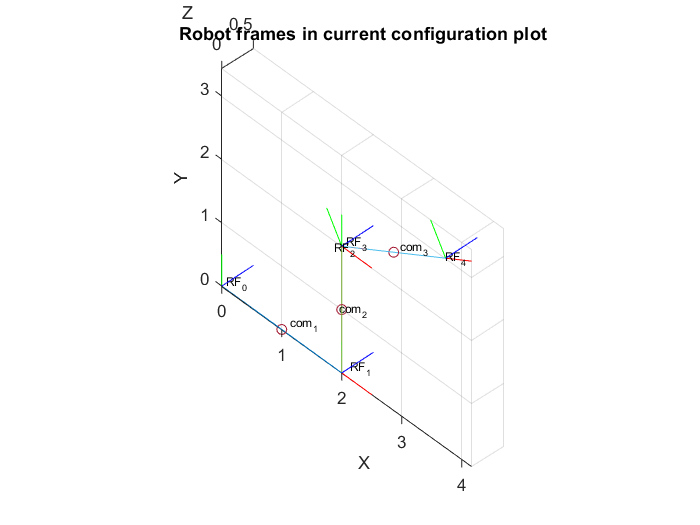

variables = [d(1), d(2), d(3), l(3), q(1), q(2), q(3)];
variables_vals = [1, 1, 1, 2, 2, 2, pi/6];

fig = showManipulator(T, r_c, variables, variables_vals);

% initialization

% v{i, j} = v_i_in_j (3 x 1)
v = cell(num_joints+1,num_joints+1); 
v_0_in_0 = zeros(3, 1);
v = set_cell(v, 0, 0, v_0_in_0);

% w{i, j} = w_i_in_j (3 x 1)
w = cell(num_joints+1,num_joints+1); 
w_0_in_0 = zeros(3, 1);
w = set_cell(w, 0, 0, w_0_in_0);

% v_c{i, j} = v_ci_in_j (3 x 1)
v_c = cell(num_joints+1,num_joints+1); 

for i=1:num_joints
    
    fprintf("======= Link %d =======", i);
    
    if(manipulator{i} == 'P')
        sigma = 1; % prismatic
    else
        sigma = 0; % revolute
    end
    
    if (motion_axis(i) == 'X')
        axis = [1; 0; 0];
    end
    if (motion_axis(i) == 'Y')
        axis = [0; 1; 0];
    end
    if (motion_axis(i) == 'Z')
        axis = [0; 0; 1];
    end
    
    % w_i_in_i = R_i-1_in_i * [w_i-1_in_i-1 + ...
    %   sigma * q_dot(i) * z_i-1_in_i-1] 
    trans = get_cell(T, i, i-1);   % T_i_in_i-1
    rot = trans(1:3, 1:3);         % R_i_in_i-1
    trasl = trans(1:3, 4);         % r_i-1,i_in_i-1
    
    w_i_in_i = rot.' * ...
        [get_cell(w, i-1, i-1) + ...
        (1 - sigma) * q_dot(i) * axis];
    w_i_in_i = simplify(collect(w_i_in_i, q_dot));
    
    if all(get_cell(r_c, i, i) == [0; 0; 0])
        v_i_in_i = get_cell(v, i-1, i-1);
        v_ci_in_i = v_i_in_i;
    else
        % v_i_in_i = R_i-1_in_i * [v_i-1_in_i-1 + ...
        %   sigma * q_dot(i) * z_i-1_in_i-1 + ...
        %   w_i_in_i-1 x r_i-1,i_in_i-1]
        v_i_in_i = rot.' * ...
                [get_cell(v, i-1, i-1) + ...
                sigma * q_dot(i) * axis] + ...
                cross(w_i_in_i, rot.'*trasl);
        v_i_in_i = collect(simplify(v_i_in_i), q_dot);
        
        % v_ci_in_i = v_i_in_i + w_i_in_i x r_ci_in_i
        v_ci_in_i = v_i_in_i + cross(w_i_in_i, get_cell(r_c, i, i));
        v_ci_in_i = collect(simplify(v_ci_in_i), q_dot);
    end
    
    trans = get_cell(T, i, 0);     % T_i_in_0
    rot = trans(1:3, 1:3);         % R_i_in_0
    trasl = trans(1:3, 4);         % r_i-1,i_in_0
    
    v_i_in_0 = collect(simplify(rot * v_i_in_i), q_dot);
    v_ci_in_0 = collect(simplify(rot * v_ci_in_i), q_dot);
    
    w = set_cell(w, i, i, w_i_in_i);
    v = set_cell(v, i, i, v_i_in_i);
    v = set_cell(v, i, 0, v_i_in_0);
    v_c = set_cell(v_c, i, i, v_ci_in_i);
    v_c = set_cell(v_c, i, 0, v_ci_in_0);
    
    fprintf("w_%d_in_%d", i, i);
    disp(w_i_in_i);
    
    fprintf("v_%d_in_%d", i, i);
    disp(v_i_in_i);
    
    fprintf("v_%d_in_0", i);
    disp(v_i_in_0);
    
    fprintf("v_c%d_in_%d", i, i);
    disp(v_ci_in_i);
    
    fprintf("v_c%d_in_0", i);
    disp(v_ci_in_0);
    
end

======= Link 1 =======

w_1_in_1

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

v_1_in_1

$$\left(\begin{array}{c} {\dot{q}}_{1}\\ 0\\ 0 \end{array}\right)$$

v_1_in_0

$$\left(\begin{array}{c} {\dot{q}}_{1}\\ 0\\ 0 \end{array}\right)$$

v_c1_in_1

$$\left(\begin{array}{c} {\dot{q}}_{1}\\ 0\\ 0 \end{array}\right)$$

v_c1_in_0

$$\left(\begin{array}{c} {\dot{q}}_{1}\\ 0\\ 0 \end{array}\right)$$

======= Link 2 =======

w_2_in_2

$$\left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

v_2_in_2

$$\left(\begin{array}{c} {\dot{q}}_{1}\\ {\dot{q}}_{2}\\ 0 \end{array}\right)$$

v_2_in_0

$$\left(\begin{array}{c} {\dot{q}}_{1}\\ {\dot{q}}_{2}\\ 0 \end{array}\right)$$

v_c2_in_2

$$\left(\begin{array}{c} {\dot{q}}_{1}\\ {\dot{q}}_{2}\\ 0 \end{array}\right)$$

v_c2_in_0

$$\left(\begin{array}{c} {\dot{q}}_{1}\\ {\dot{q}}_{2}\\ 0 \end{array}\right)$$

======= Link 3 =======

w_3_in_3

$$\left(\begin{array}{c} 0\\ 0\\ {\dot{q}}_{3} \end{array}\right)$$

v_3_in_3

$$\left(\begin{array}{c} \cos\left(q_{3}\right)\,{\dot{q}}_{1}+\sin\left(q_{3}\right)\,{\dot{q}}_{2}\\ \left(-\sin\left(q_{3}\right)\right)\,{\dot{q}}_{1}+\cos\left(q_{3}\right)\,{\dot{q}}_{2}\\ 0 \end{array}\right)$$

v_3_in_0

$$\left(\begin{array}{c} {\dot{q}}_{1}\\ {\dot{q}}_{2}\\ 0 \end{array}\right)$$

v_c3_in_3

$$\left(\begin{array}{c} \cos\left(q_{3}\right)\,{\dot{q}}_{1}+\sin\left(q_{3}\right)\,{\dot{q}}_{2}\\ \left(-\sin\left(q_{3}\right)\right)\,{\dot{q}}_{1}+\cos\left(q_{3}\right)\,{\dot{q}}_{2}+d_{3}\,{\dot{q}}_{3}\\ 0 \end{array}\right)$$

v_c3_in_0

$$\left(\begin{array}{c} {\dot{q}}_{1}+\left(-d_{3}\,\sin\left(q_{3}\right)\right)\,{\dot{q}}_{3}\\ {\dot{q}}_{2}+\left(d_{3}\,\cos\left(q_{3}\right)\right)\,{\dot{q}}_{3}\\ 0 \end{array}\right)$$

% K{i} = kinetic energy of link i
% U{i} = potential energy of link i
K = num2cell(NaN(1, num_joints));
U = num2cell(NaN(1, num_joints));
K_tot = 0;
U_tot = 0;
for i=1:num_joints
    
    v_ci_in_i = get_cell(v_c, i, i);
    w_i_in_i = get_cell(w, i, i);
    K{i} = simplify(1/2 * m(i) * (v_ci_in_i.' * v_ci_in_i) + ...
        1/2 * (w_i_in_i.' * I(i) * w_i_in_i));
    U{i} = simplify(-m(i) * [0 -g0 0] * get_cell(r_c, i, 0));
    
    fprintf("Kinetic energy of link %d\n", i);
    disp(K{i});
    fprintf("Potential energy of link %d\n", i);
    disp(U{i});
    
    K_tot = simplify(expand(K_tot + K{i}));
    U_tot = simplify(expand(U_tot + U{i}));
    
end

Kinetic energy of link 1


$$\frac{m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

Potential energy of link 1


$$0$$

Kinetic energy of link 2


$$\frac{m_{2}\,\left({{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}$$

Potential energy of link 2


$$-g_{0}\,m_{2}\,\left(d_{2}-q_{2}\right)$$

Kinetic energy of link 3


$$\frac{\mathrm{I3zz}\,{{\dot{q}}_{3}}^{2}}{2}+\frac{m_{3}\,\left({\left({\dot{q}}_{1}\,\cos\left(q_{3}\right)+{\dot{q}}_{2}\,\sin\left(q_{3}\right)\right)}^{2}+{\left(d_{3}\,{\dot{q}}_{3}+{\dot{q}}_{2}\,\cos\left(q_{3}\right)-{\dot{q}}_{1}\,\sin\left(q_{3}\right)\right)}^{2}\right)}{2}$$

Potential energy of link 3


$$g_{0}\,m_{3}\,\left(q_{2}+d_{3}\,\sin\left(q_{3}\right)\right)$$

Robot inertia matrix

M = expand(jacobian(jacobian(K_tot, q_dot),q_dot)); % function of q
M

$$M = \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & 0 & -d_{3}\,m_{3}\,\sin\left(q_{3}\right)\\ 0 & m_{2}+m_{3} & d_{3}\,m_{3}\,\cos\left(q_{3}\right)\\ -d_{3}\,m_{3}\,\sin\left(q_{3}\right) & d_{3}\,m_{3}\,\cos\left(q_{3}\right) & m_{3}\,{d_{3}}^{2}+\mathrm{I3zz} \end{array}\right)$$


% optional
% M_a = M;
% M_a(1,1) = collect(expand(subs(M(1,1), sin(q(2))^2, (1-cos(q(2))^2))), cos(q(2))^2);
% M_a = subs(M_a, I{1}(2,2) + I{2}(1,1), a(1));
% M_a = subs(M_a, (m(2)*d(2)^2 - I{2}(1,1) + I{2}(2,2)), a(2));
% M_a = subs(M_a, m(2)*d(2)^2 + I{2}(3, 3), a(3));
% M = simplify(M_a);
% M

Coriolis and centrifugal terms

c = [];
for i=1:num_joints
    C_i = 1/2 * ( jacobian(M(:,i), q) + jacobian(M(:,i), q).' - diff(M, q(i)) );
    c = [c; expand(q_dot * C_i * q_dot.')];
end
c = simplify(c);
c

$$c = \left(\begin{array}{c} -d_{3}\,m_{3}\,{{\dot{q}}_{3}}^{2}\,\cos\left(q_{3}\right)\\ -d_{3}\,m_{3}\,{{\dot{q}}_{3}}^{2}\,\sin\left(q_{3}\right)\\ 0 \end{array}\right)$$

Gravity terms

g = expand(jacobian(U_tot, q).');
g

$$g = \left(\begin{array}{c} 0\\ g_{0}\,m_{2}+g_{0}\,m_{3}\\ d_{3}\,g_{0}\,m_{3}\,\cos\left(q_{3}\right) \end{array}\right)$$


% optional
% g_a = g;
% g_a = subs(g_a, d(2)*g0*m(2), a(4));
% g = simplify(g_a);
% g

Show complete dynamic equations

% model = M*q_ddot.' + c + g + diag(F)*q_dot.'; % == u.';
% model = expand(model);
% % model
% 
% % optional
% model = collect(model, [q_ddot, q_dot, q]);
% 
% model = subs(model, F(1), a(5));
% model = subs(model, F(2), a(6));
% % res = collect(res, a4);
% % res = collect(res, a5);
% model

## Linear parametrization

% Y = cell(num_joints, size(a, 2)); % regressor matrix
% 
% for i=1:num_joints
%     model_row = expand(model(i));
%     for j=1:size(a, 2)
%         coeff = coeffs(model_row, a(j));
%         if size(coeff, 2) > 1
%            Y{i, j} = sum(coeff(2:end)); 
%         else
%            Y{i, j} = 0;
%         end
%     end
% end
% Y